# ECSE 343 Final Exam Question1 (15 Marks)

Posted at 9:00AM April 19, 2021

Due at 9:00AM April 22, 2021

**This final has three Questions. Each question is submitted as a seperate 'assignment'.** 

## **Question 1**

Your are given the results of an experpiment which are stored in Q1data.mat

Note that given the type of experiment, you know that YQ1data contains zero-mean gaussian noise. 

You may run the following code in order to display the data (make sure Q1data.mat is in your working directory):

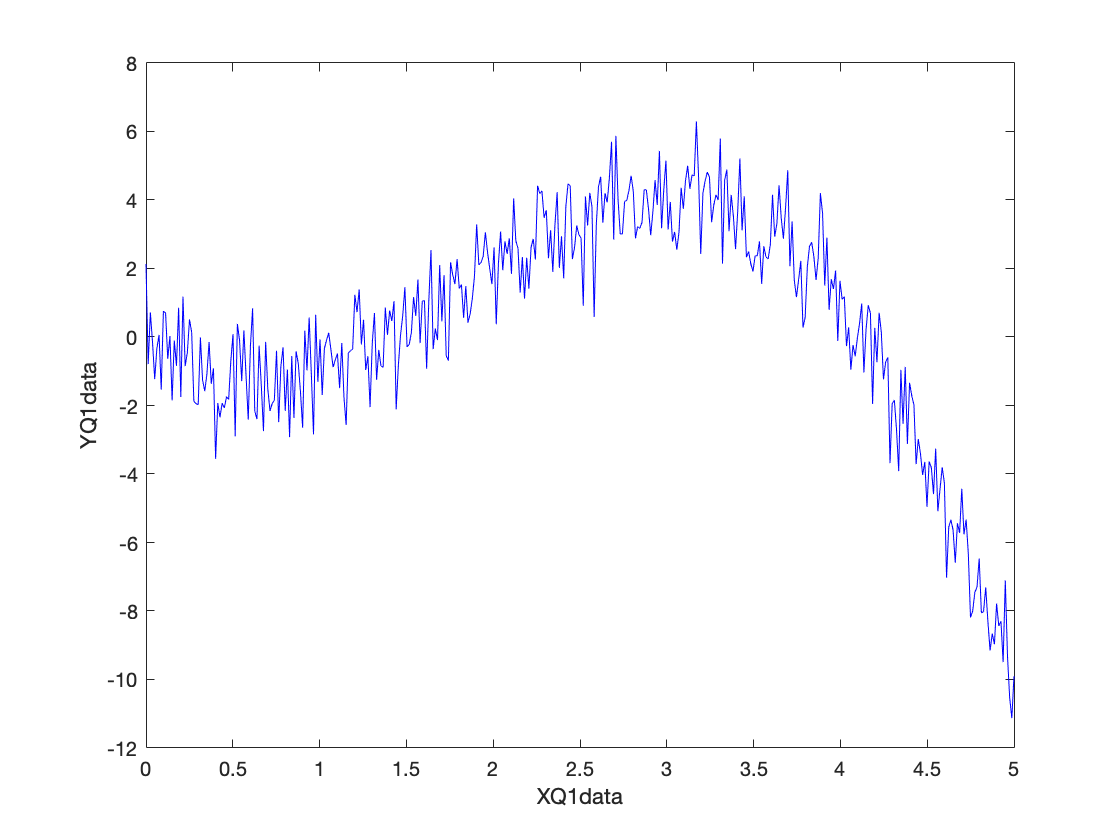

clearvars
clf
load Q1data
plot(XQ1data,YQ1data,'b')
xlabel('XQ1data')
ylabel('YQ1data')

**Part 1 (8 Points)**

Use the techniques we studied in this course in order to find a plot a better estimate of YQ1data and store it in YQ1est. You may use (if needed) the following matlab builtin functions: qr, lu, chol, svd, eig, polyval, and the '\' operator as in x = A\b. Include and run your code below

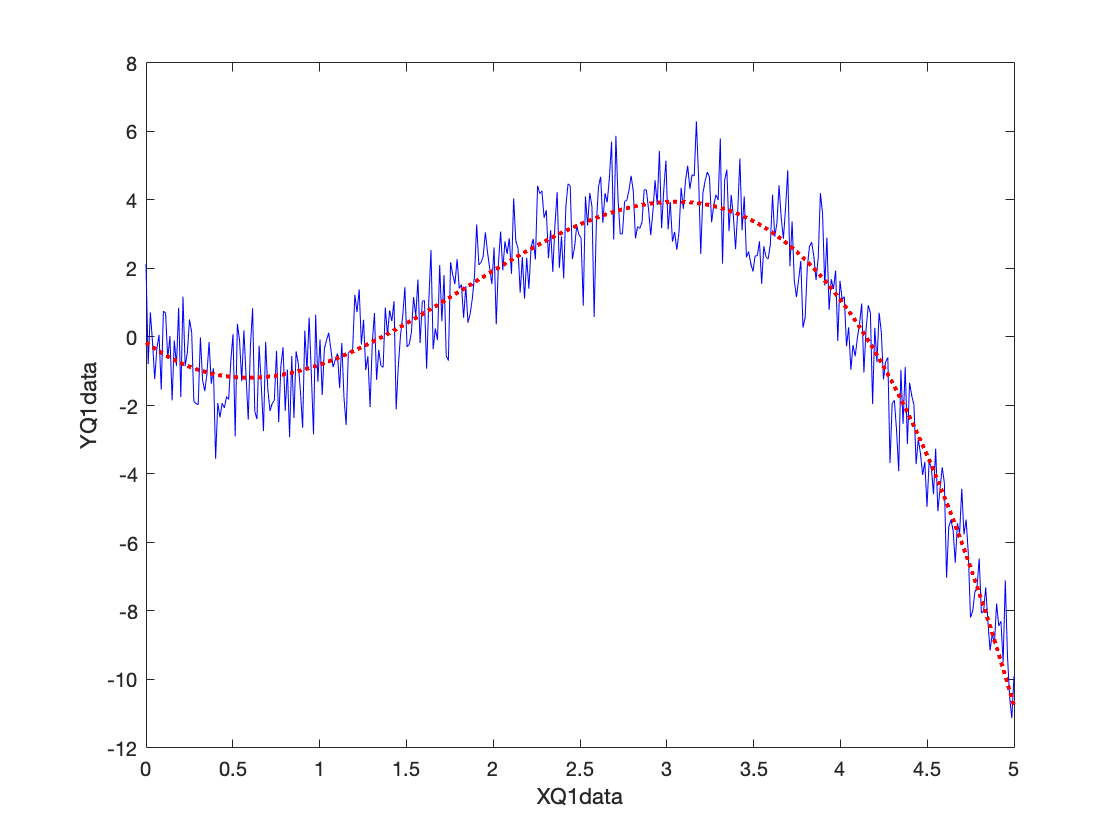

% Load and plot original data
clear all
clf
load Q1data

%fitting polynomial degree
deg = 3;

%evaluate polynomial matrix 
M = zeros(size(XQ1data,2), deg+1);
for i=1:size(M)
     x = XQ1data';
     M(i,:) = x(i);
     M(i,:) = M(i, :) .^ (0:1:deg);
end


%QR decompose polynomial matrix
[L,U] = lu(M);

%Solve for A 
X = (L * U) \ YQ1data';

%Solve for Y
YQ1est = zeros(length(XQ1data'),1);
powers = 0:deg;
for I = 1:length(powers)
   YQ1est = YQ1est + X(I)*XQ1data'.^powers(I);
end

% Plot the results of your estimate and compare to original data
% The code below assumes you have already computed YQ1est 
plot(XQ1data,YQ1data,'b')
xlabel('XQ1data')
ylabel('YQ1data')
hold on
plot(XQ1data,YQ1est,'r:','LineWidth',2)

**Part 2 (4 Marks)**

*Describe using equations and words the the algorithm/techniques us used in part 1. Justify your choices methods used and for the parameters you used in your models. You may type your answer below. or include it in an attached pdf file. If you choose the latter, please put a note below indicating that the answer is in the attached pdf file.*

To fit the data containing mean Gaussian noise, y, polynomial fitting is used. We need to solve the equation Mx = y, where y is the data and M is a polynomial matrix (a matrix of with the bases of the polynomial space (monomials) stacked into rows). M is constructed using d monomials, where d is the desired degree of the polynomial. The vector x are the coefficients of the polynomial which must be slved for by solving the systeem Mx = y. 

There are multiple ways to solve this system. A simple method is QR decomposition, which decomposes M into the product of an orthogonal matrrix and an upper triangular one, and is more numerically stable than the matrix inverse of M due to the lower condition number of QR. 

QR and Cholesky decompositions could also be used to achieve this task, and do produce the same results, but as the matrix M is not ill conditioned, one can simply used the fast LU decomposition.  

To select the degree off the polynomial, the degree was increased from 0 until the cuve no longe underfit the data, such as in the linear and quadratic cases. A degree of 3 seems to do the trick. 

**Part 3 (3 Marks)**

*What techniques did you use in order to improve accuracy? Justify your choices. You may type your answer below. or include it in an attached pdf file. If you choose the latter, please put a note below indicating that the answer is in the attached pdf file.*

Accuracy was improved by selecting a degree for which the curve did not overfit or underfit. To select the degree off the polynomial, the degree was increased from 0 until the cuve no longe underfit the data, such as in the linear and quadratic cases. A degree of 3 seems to do the trick. 